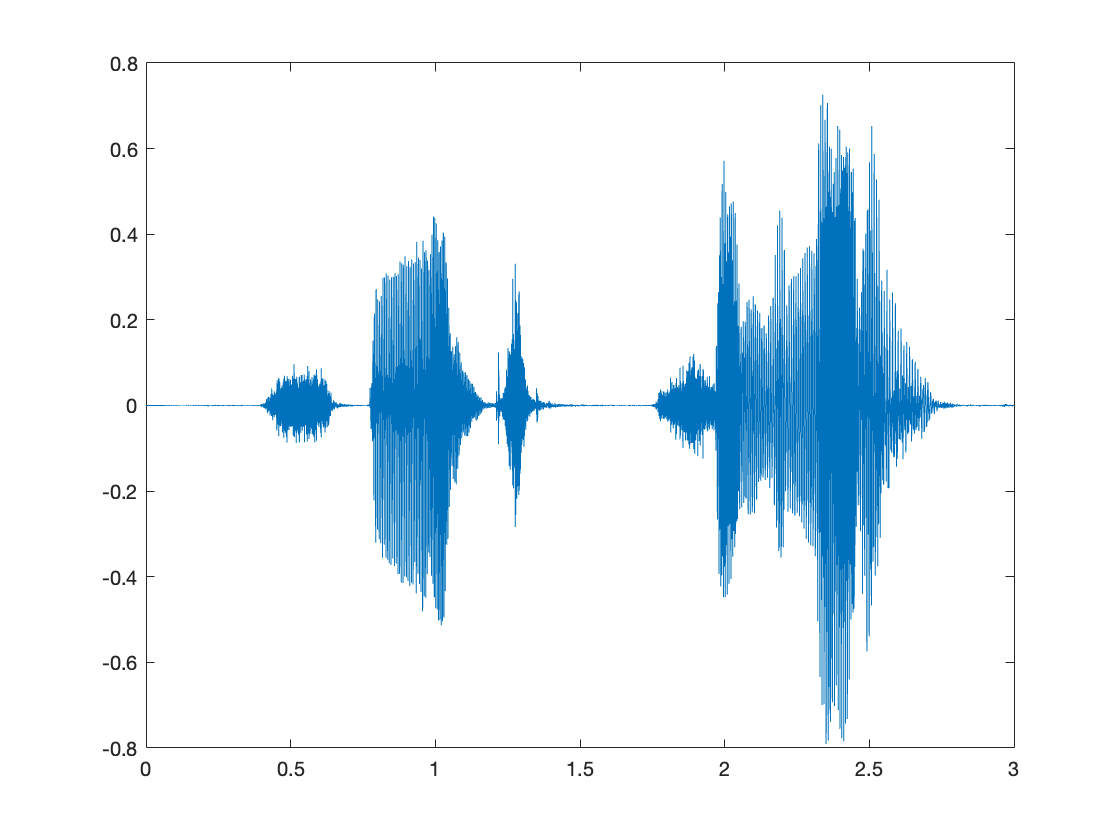

%Original audio Bits/sample = 16 and Fs = 16k Hz
[y,Fs] = audioread('Lab4.wav');

%time duration of the given audio file 
time_duration = length(y)/Fs;

%generating the time axis
t = 0 : 1/Fs : time_duration - 1/Fs;


plot(t,y);

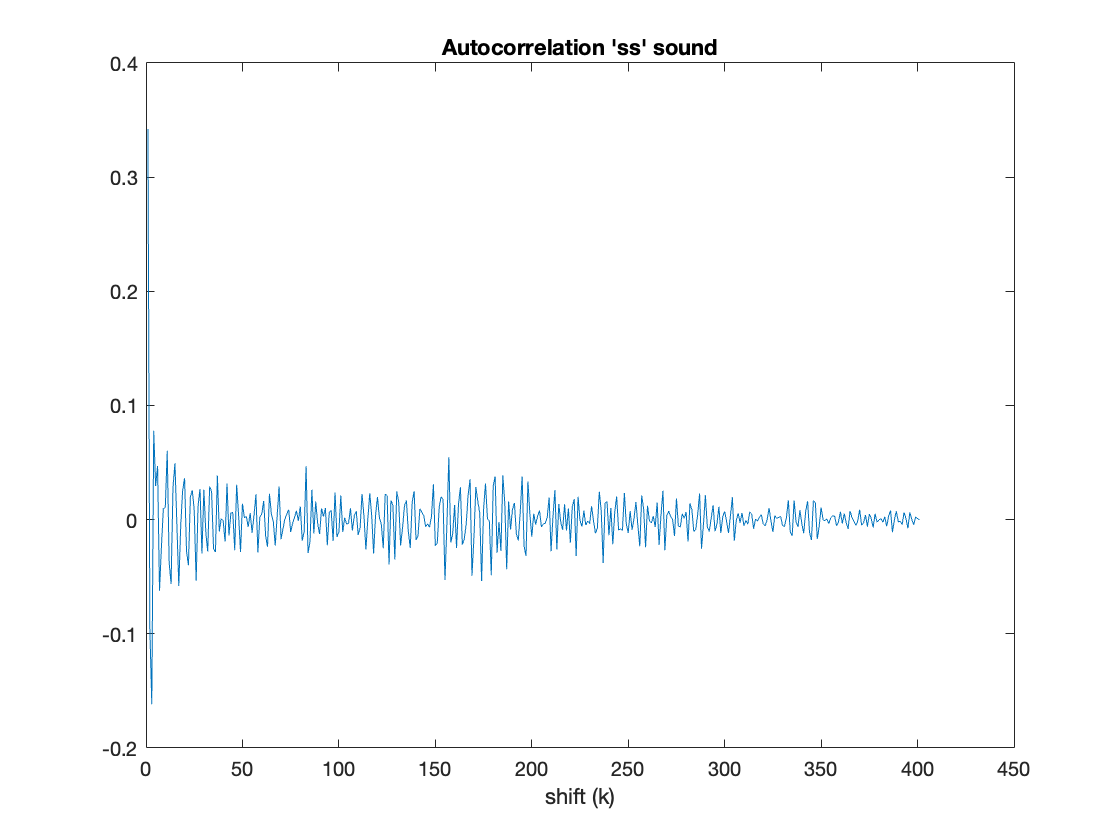


ss_sound = y(Fs*0.53:Fs*0.555);
ch_sound = y(Fs*1.275:Fs*1.3);
ii_sound = y(Fs*0.9:Fs*0.925);
n_sound = y(Fs*2.24:Fs*2.265);

ss_a = AutoCorr(ss_sound);
plot(ss_a)
title("Autocorrelation 'ss' sound");
xlabel("shift (k)");

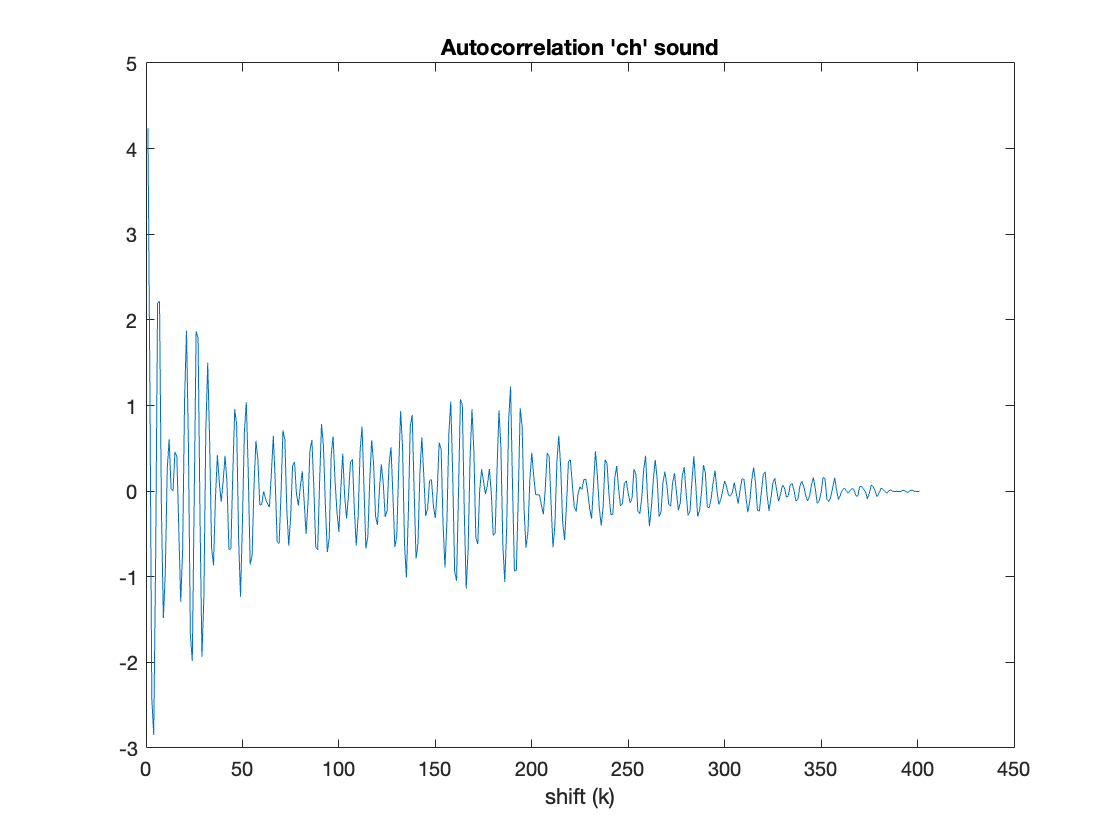


ch_a = AutoCorr(ch_sound);
plot(ch_a);
title("Autocorrelation 'ch' sound");
xlabel("shift (k)");

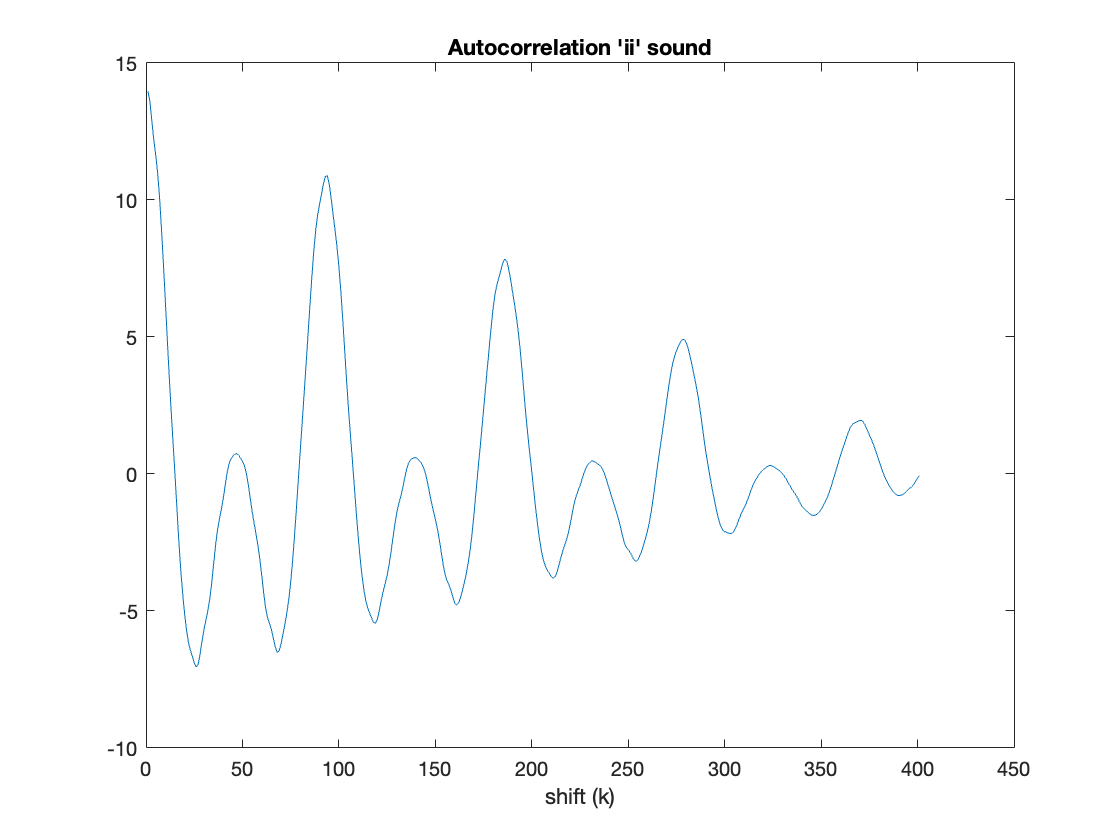


ii_a = AutoCorr(ii_sound);
plot(ii_a);
title("Autocorrelation 'ii' sound");
xlabel("shift (k)");

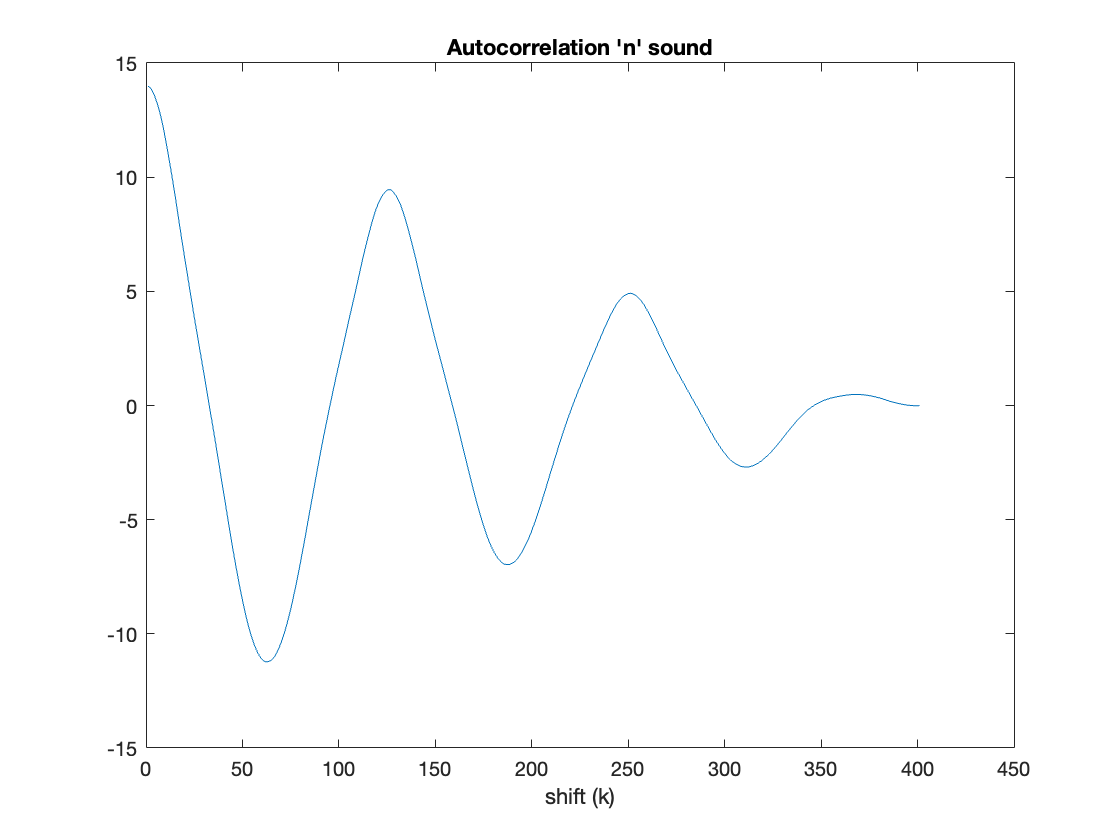


n_a = AutoCorr(n_sound);
plot(n_a);
title("Autocorrelation 'n' sound");
xlabel("shift (k)");

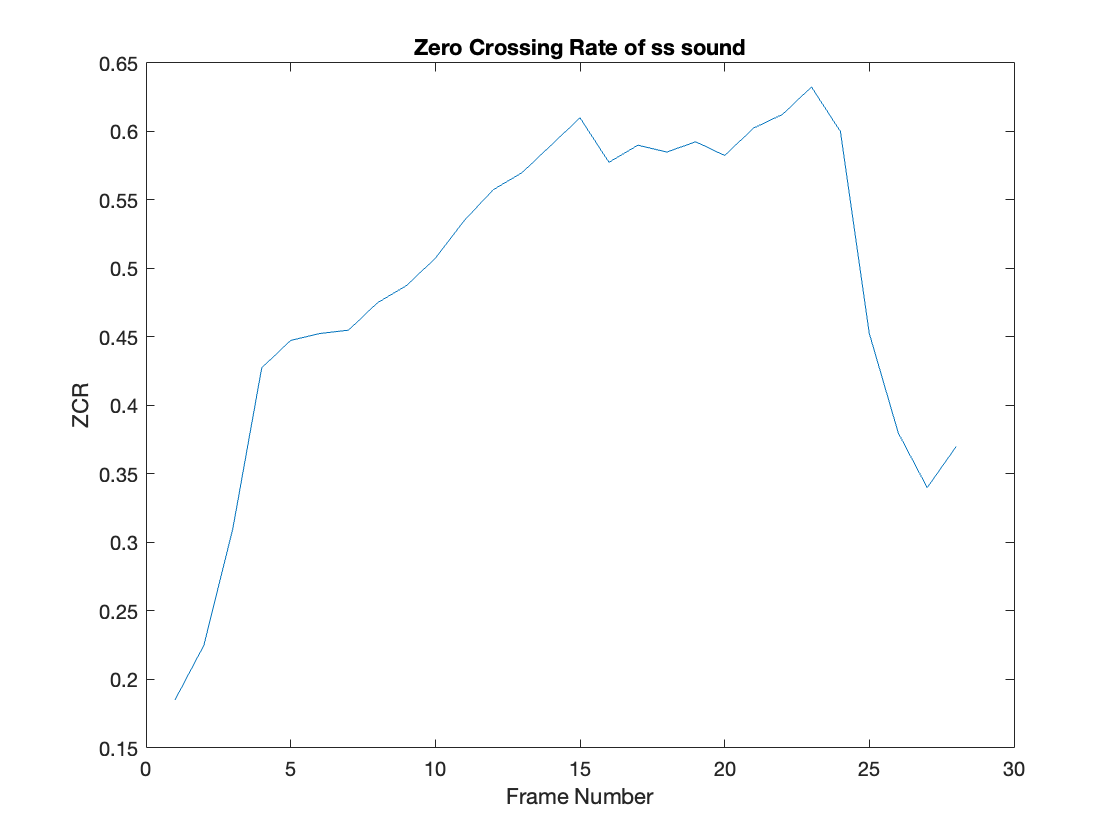


ss_sound = y(Fs*0.38:Fs*0.68);
ii_sound = y(Fs*0.77:Fs*1.15);
ch_sound = y(Fs*1.2:Fs*1.37);
n_sound = y(Fs*2.2:Fs*2.30);
noise = y(Fs*0.19:Fs*0.34);

%25ms = 400 samples
frameSize = 400;

%10ms = 160 samples
frameShift = 160;

%zcr of the given sounds
ZCR(ss_sound,frameSize,frameShift,"ss sound");

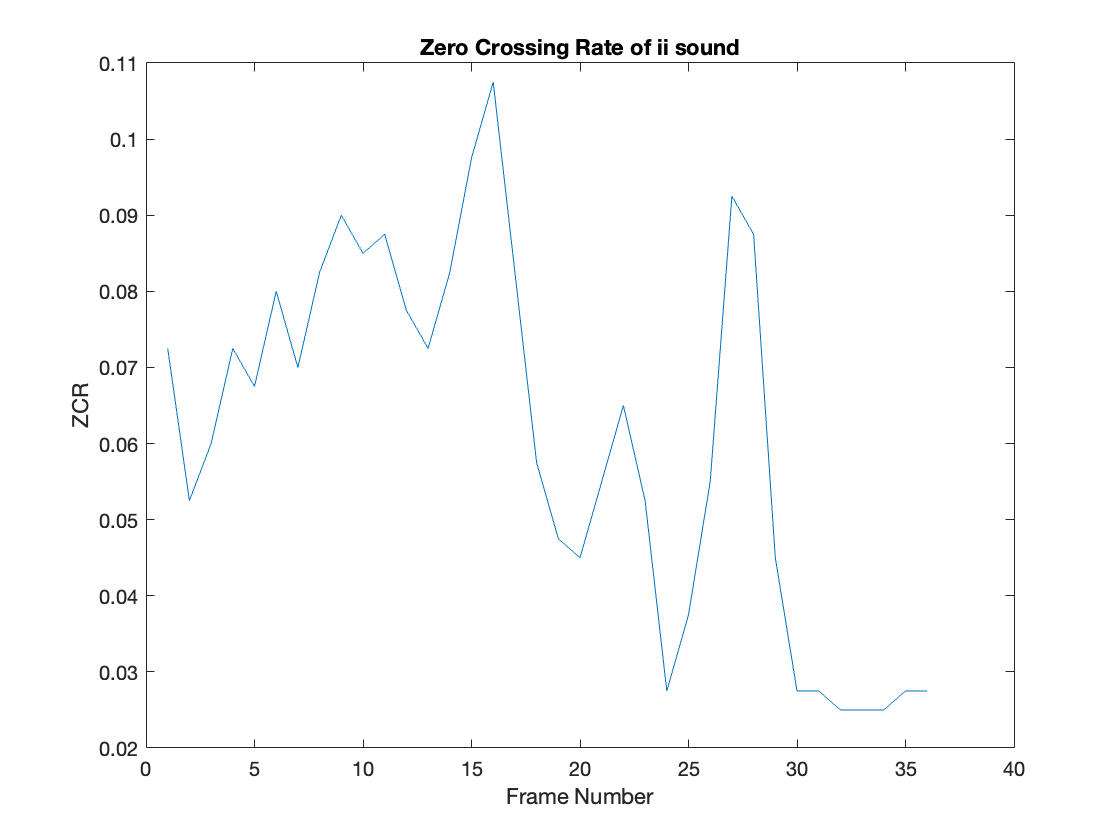

ZCR(ii_sound,frameSize,frameShift,"ii sound");

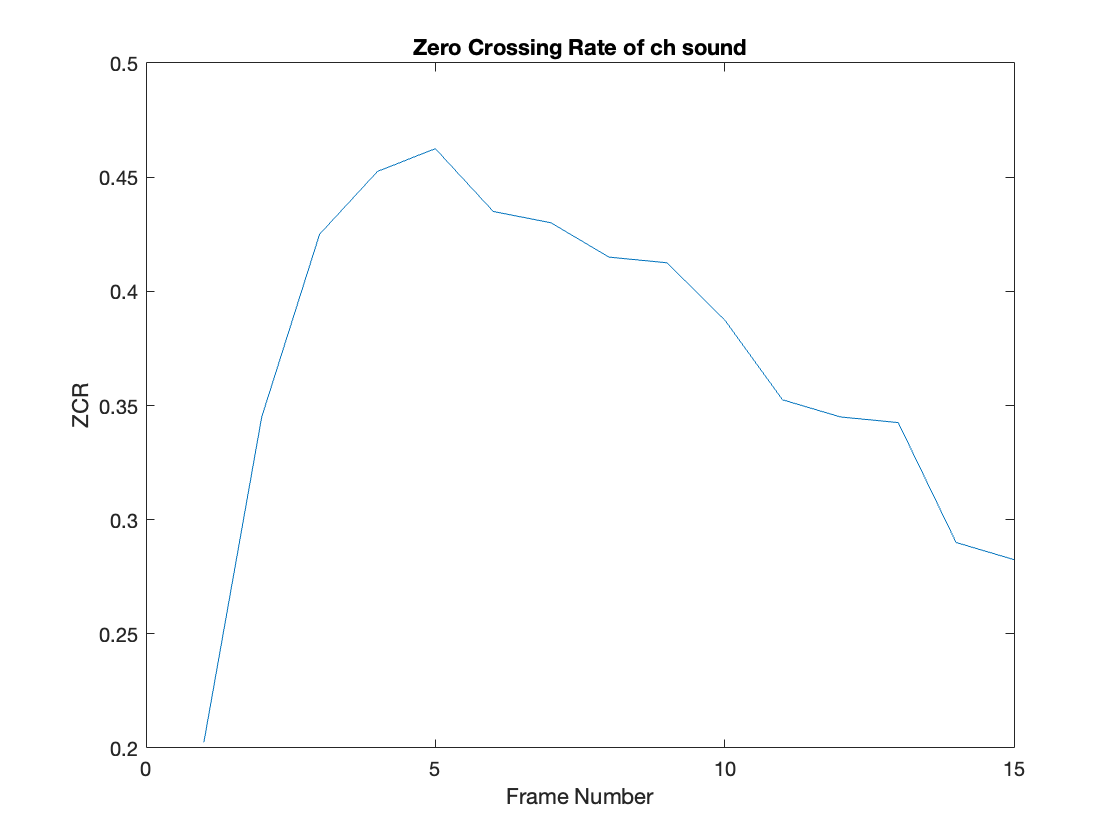

ZCR(ch_sound,frameSize,frameShift,"ch sound");

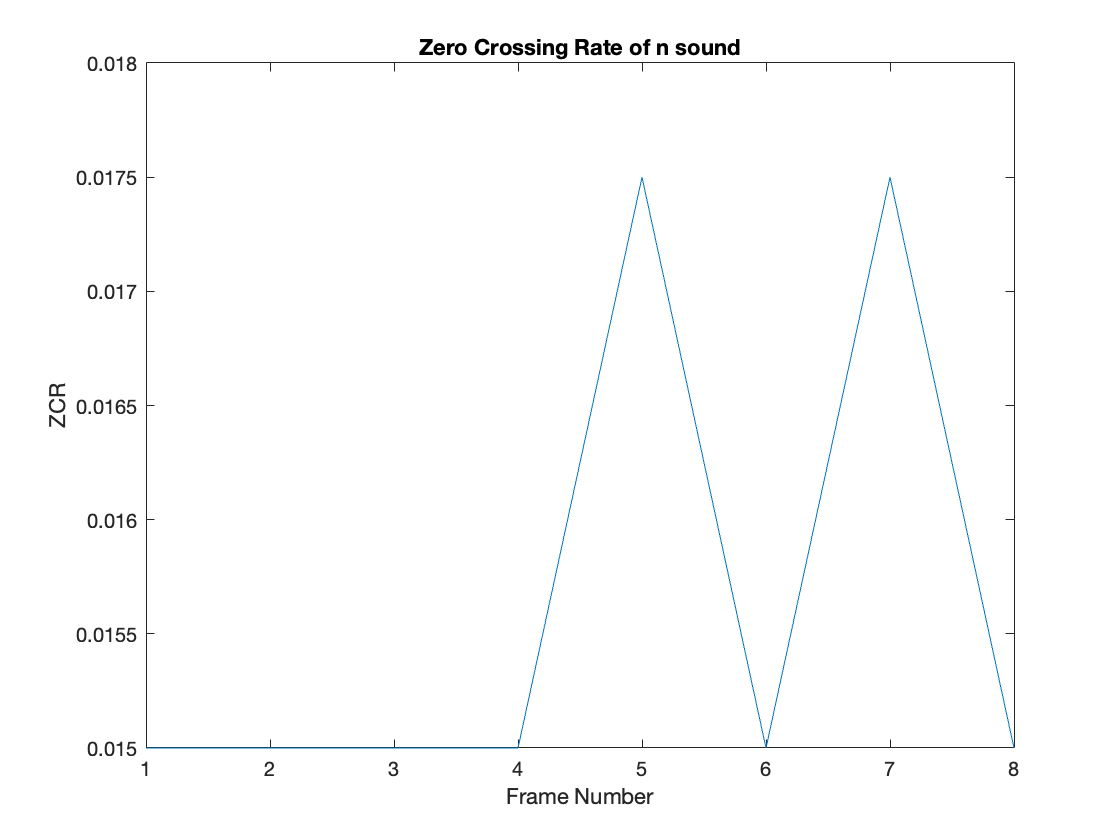

ZCR(n_sound,frameSize,frameShift,"n sound");

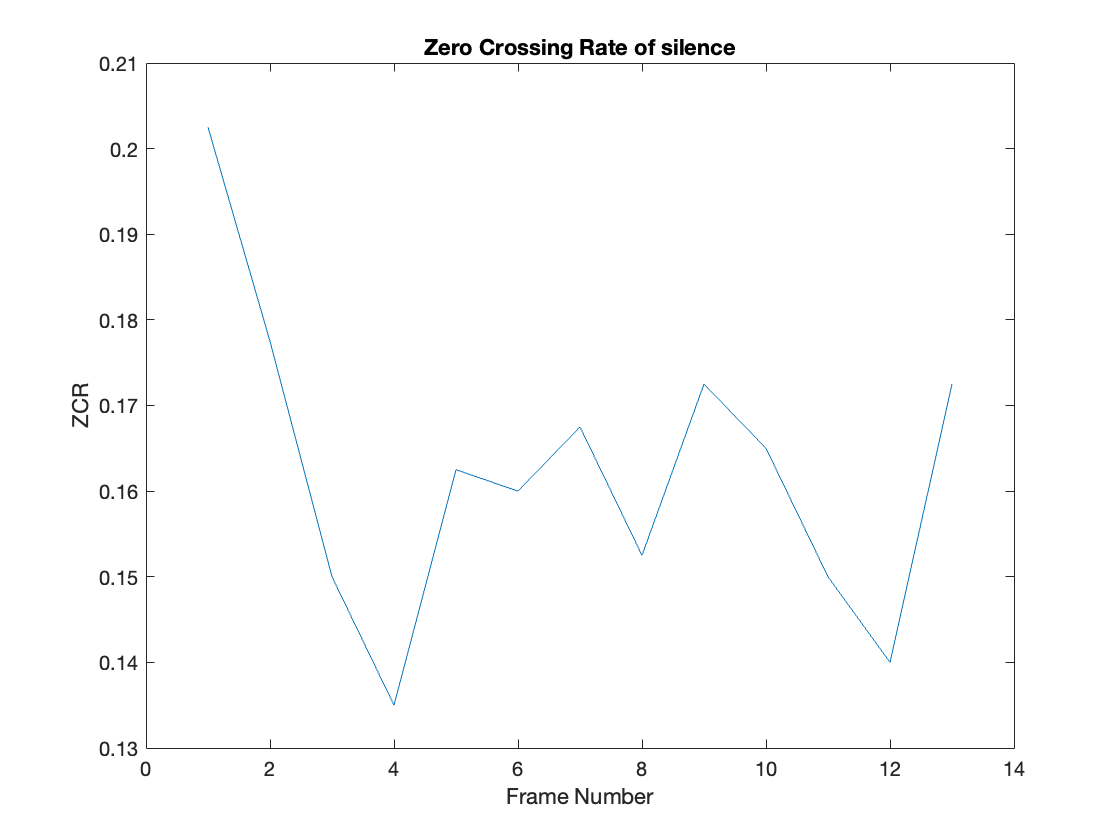

ZCR(noise,frameSize,frameShift,"silence");

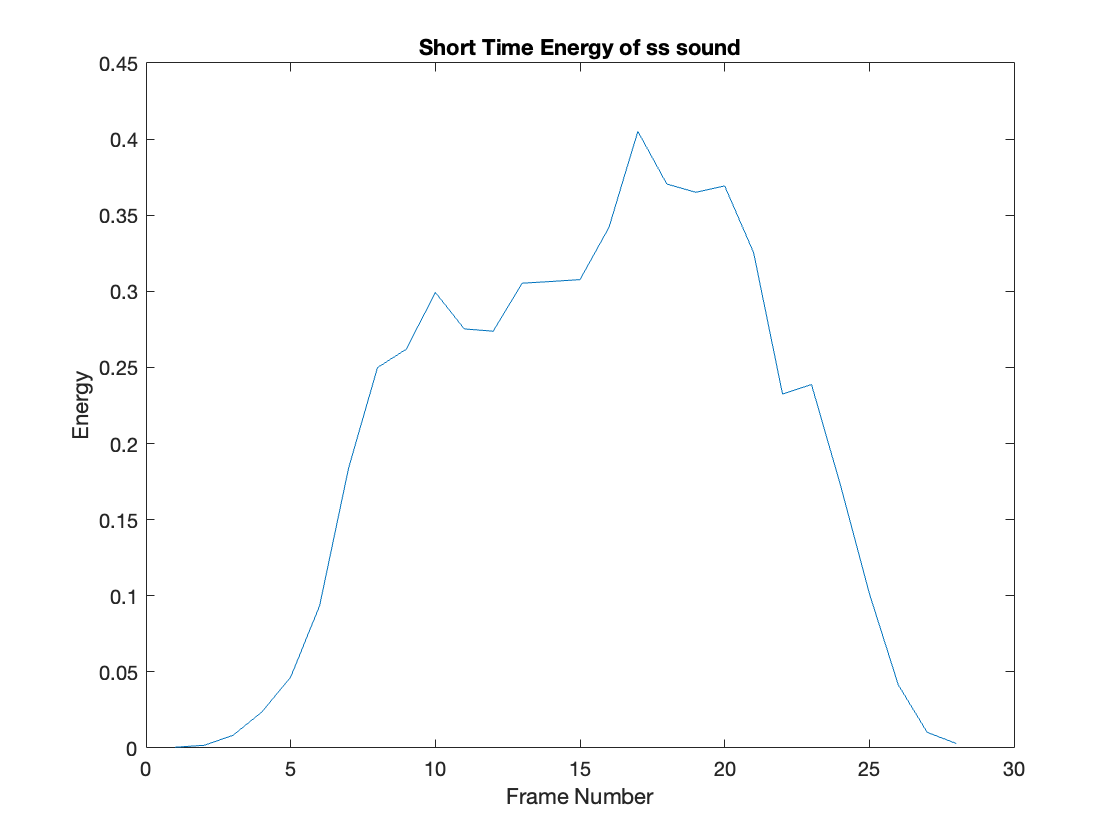


STE(ss_sound,frameSize,frameShift,"ss sound");

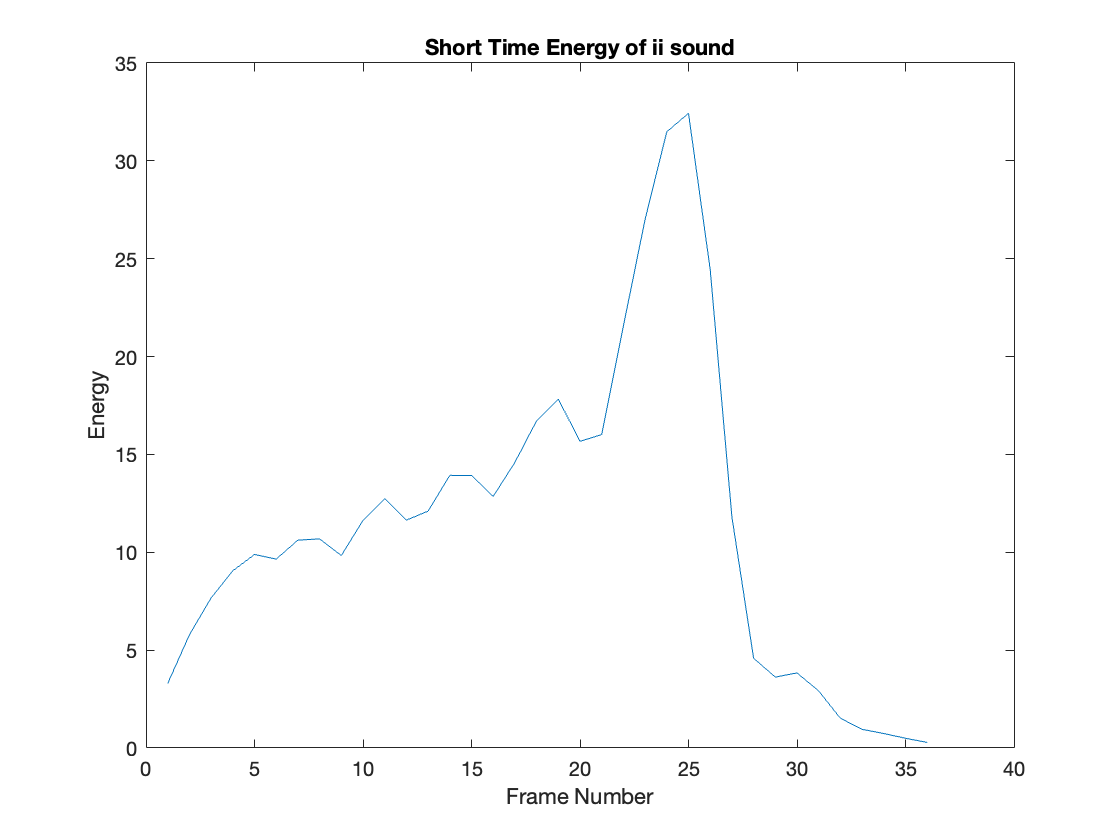

STE(ii_sound,frameSize,frameShift,"ii sound");

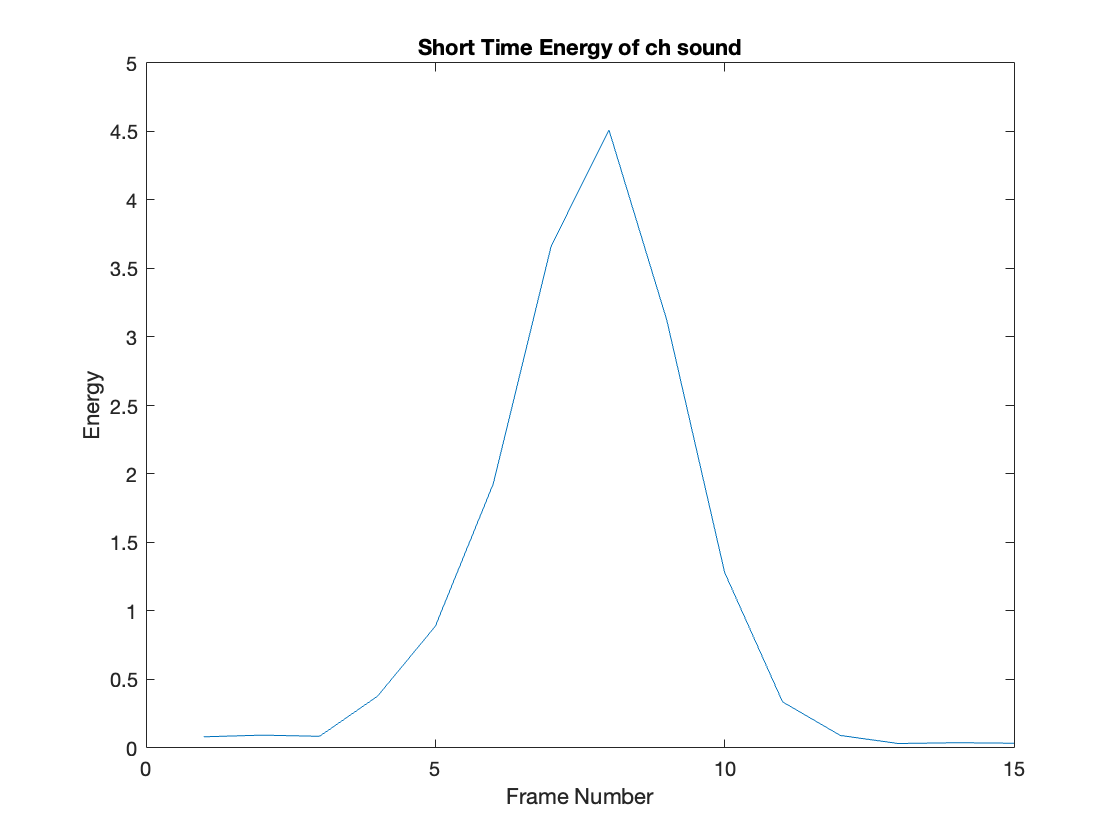

STE(ch_sound,frameSize,frameShift,"ch sound");

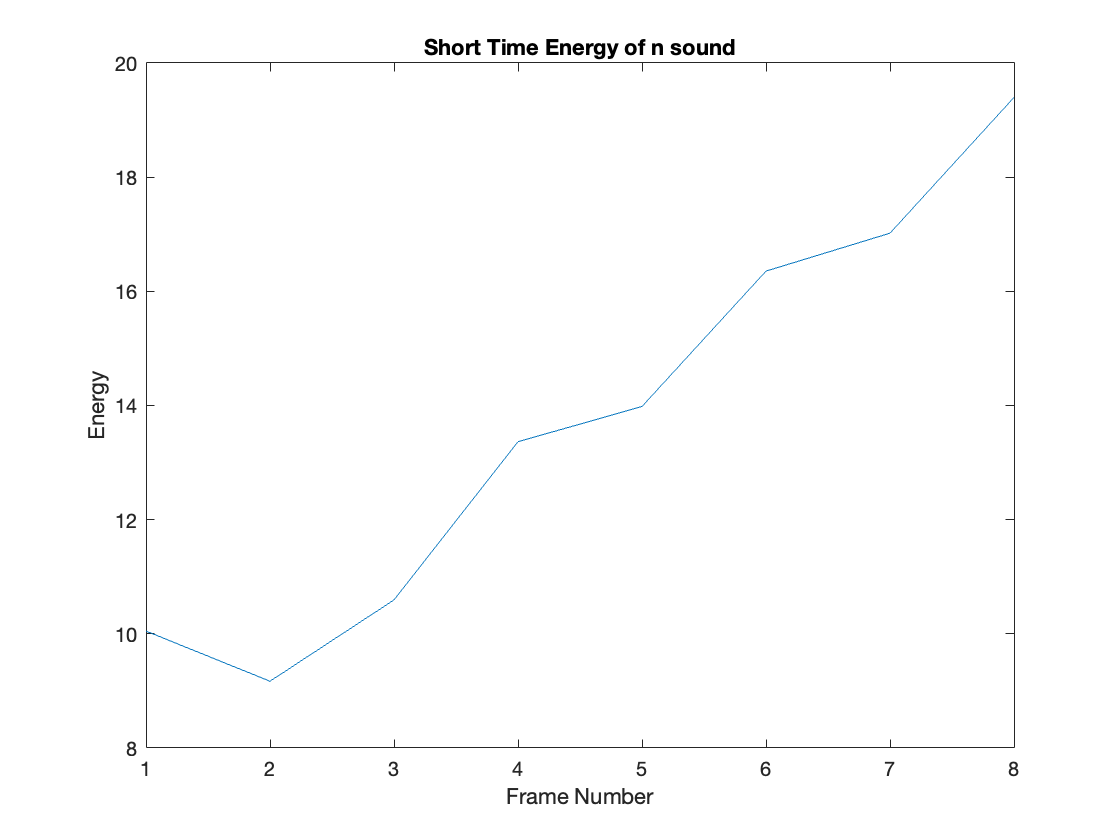

STE(n_sound,frameSize,frameShift,"n sound");

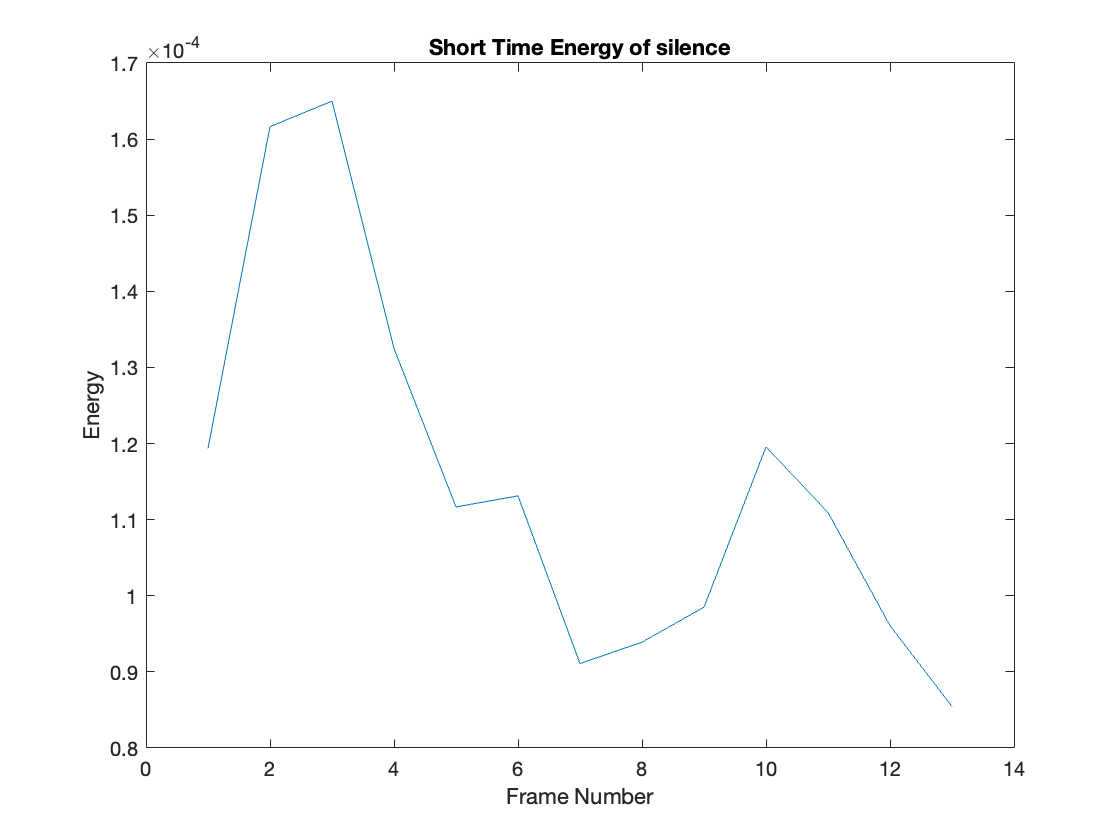

STE(noise,frameSize,frameShift,"silence");

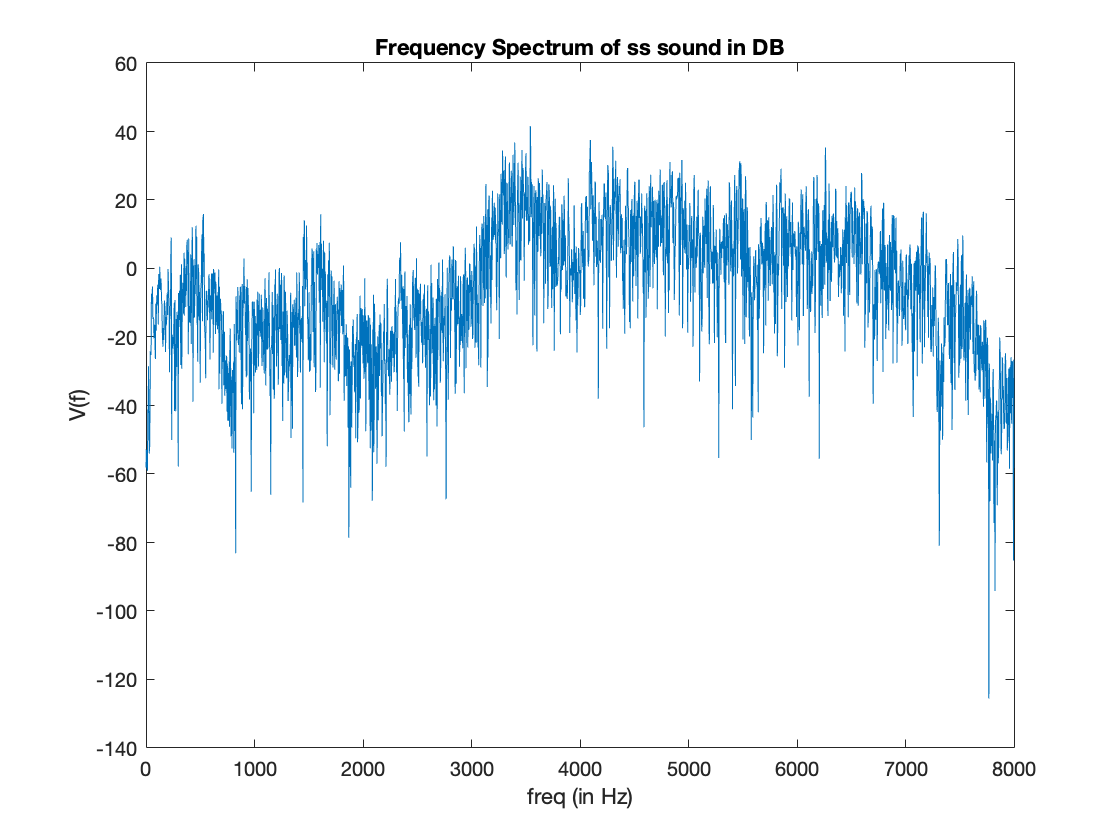


speechfft(ss_sound,Fs,"ss sound");

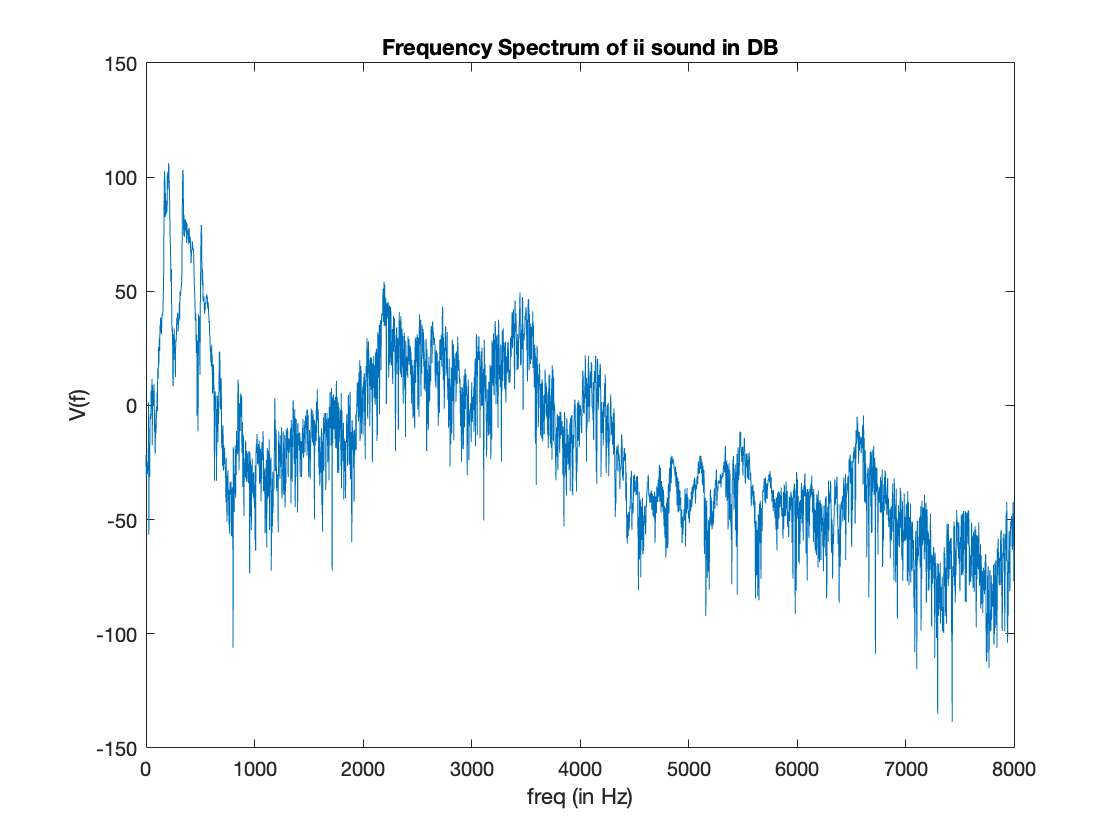

speechfft(ii_sound,Fs,"ii sound");

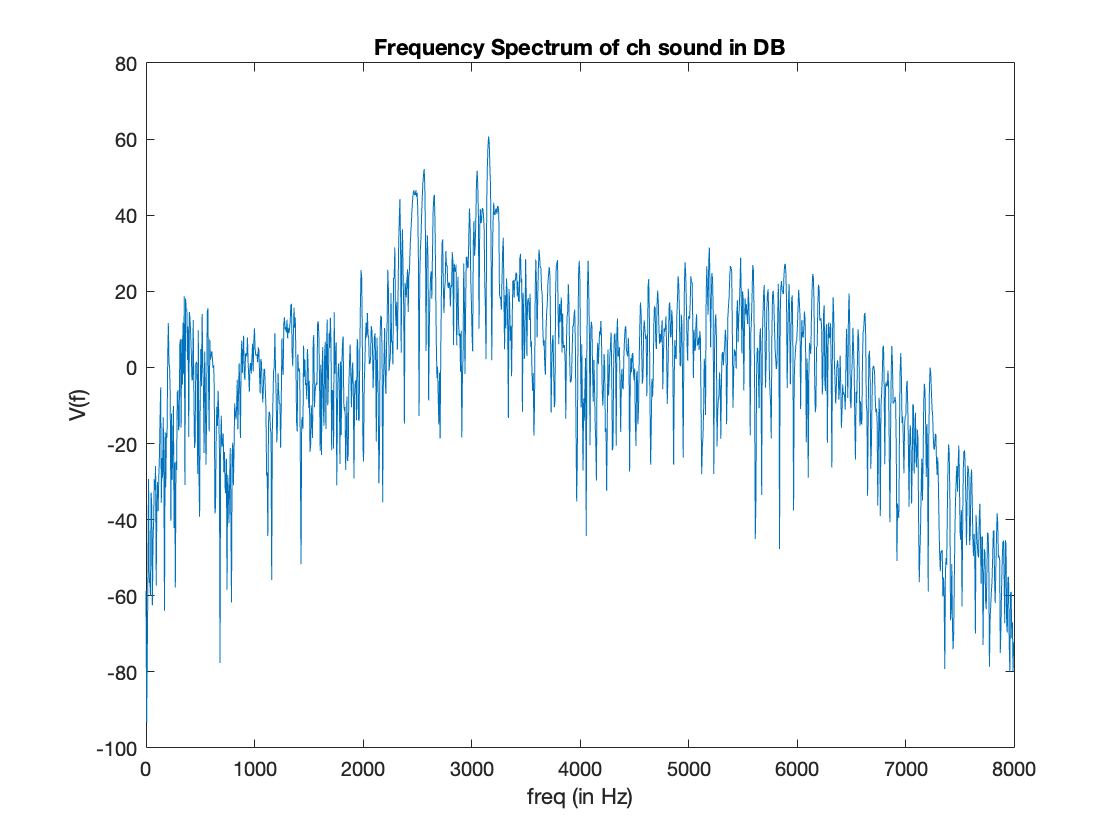

speechfft(ch_sound,Fs,"ch sound");

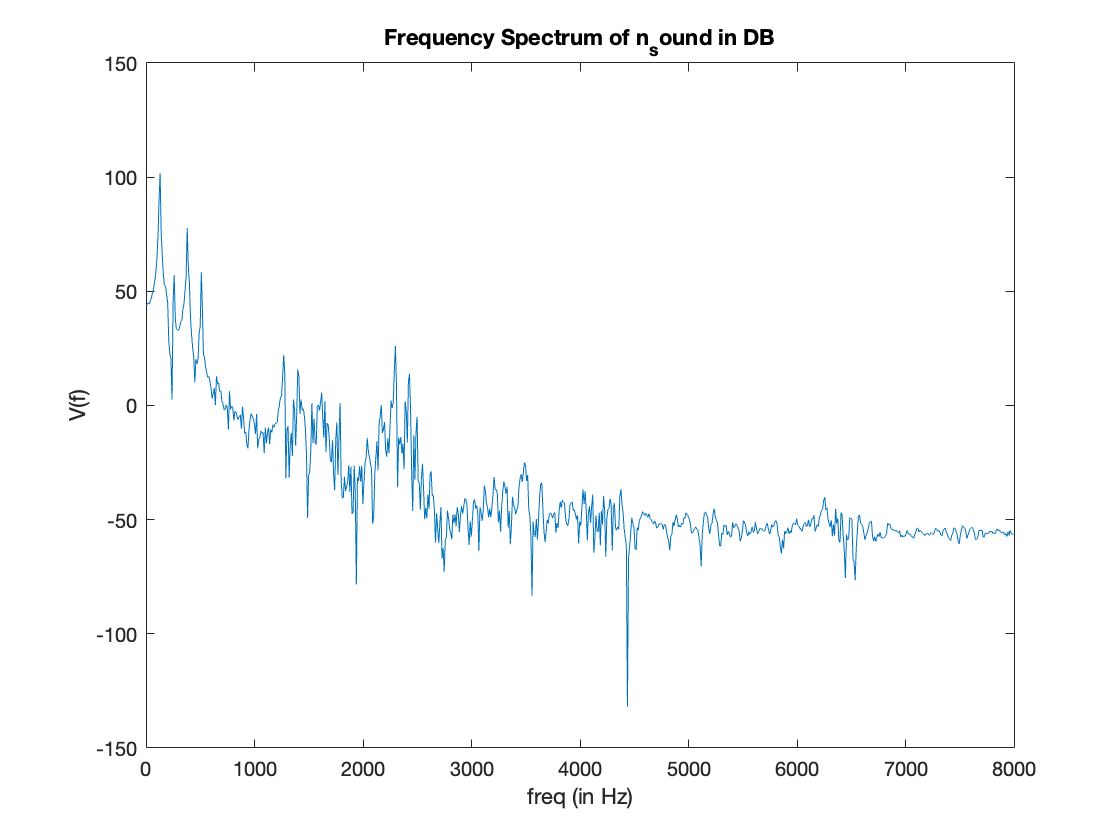

speechfft(n_sound,Fs,"n_sound");

function [] = speechfft(x,Fs,text)
    
    fftFull = fft(x);
    
    %length of the FFT of non stationary signal in frequency domain
    Len_f = length(fftFull);  
    
    %Taking only +ve frequencies
    fftHalf = fftFull(1:round(Len_f/2));
    
    %converting in DB scale
    fftDB = 20*log(abs(fftHalf));
    
    %iterating freq from 0 to +len/2
    freq = 0 : 1 : round(Len_f/2) - 1; 
    
    %converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
    freq = Fs*freq/Len_f; 
    
    %Plotting
    plot(freq,fftDB);
    title("Frequency Spectrum of " + text + " in DB");
    xlabel("freq (in Hz)");
    ylabel("V(f)");
    
end


function autocorr = AutoCorr(y)

    autocorr = [];

    for shift = 0 : length(y) - 1
        
        buf = 0;
        
        for i = 1:length(y) - shift
           
            buf = buf + y(i)*y(i+shift);
            
        end
       
        autocorr = [autocorr buf];
        
    end
    
end

function zcr = ZCR(y,frameSize,frameShift,text)

    %number of windows
    numWindows = floor((length(y) - frameSize)/frameShift) + 1;
    
    %Array to store zcr
    zcr = [];

    
    %iterating the windows
    for i = 1 : numWindows
        
        %determining the start and end of the given window
        winstart = 1 + frameShift*(i-1);
        
        winend = winstart + frameSize;
        
        %buffer varible
        buf = 0;
        
        %iterating from starting of window to end of window
        for j = winstart : winend - 1
            
            %incrementing if two consequtive elements have opposite sign
            if(y(j)*y(j+1) <= 0)
                buf = buf + 1;
            end
            
        end
        
        %division by frame size to compute rate
        buf = buf/frameSize;
        
        %appending calulated zcr for the current frame.
        zcr = [zcr buf];

    end
    
    %plotting
    plot(zcr);
    title("Zero Crossing Rate of " + text);
    xlabel("Frame Number");
    ylabel("ZCR");
    
end

function ste = STE(y,frameSize,frameShift,text)

    %number of windows
    numWindows = floor((length(y) - frameSize)/frameShift) + 1;
    
    %Array to store zcr
    ste = [];

    
    %iterating the windows
    for i = 1 : numWindows
        
        %determining the start and end of a given window
        winstart = 1 + frameShift*(i-1);
        
        winend = winstart + frameSize;
        
        %buffer varible
        buf = 0;
        
        %iterating from starting of window to end of window
        for j = winstart : winend - 1
            
            buf = buf + y(j)*y(j);
            
        end
        
        %appending calulated ste for the current frame.
        ste = [ste buf];
        
    end
    
    %plotting
    plot(ste);
    title("Short Time Energy of " + text);
    xlabel("Frame Number");
    ylabel("Energy");
    
    
end



